## Generate artificial data

clear all;

x = -4:0.05:4;
y = -4:0.05:4;

rng(123456);

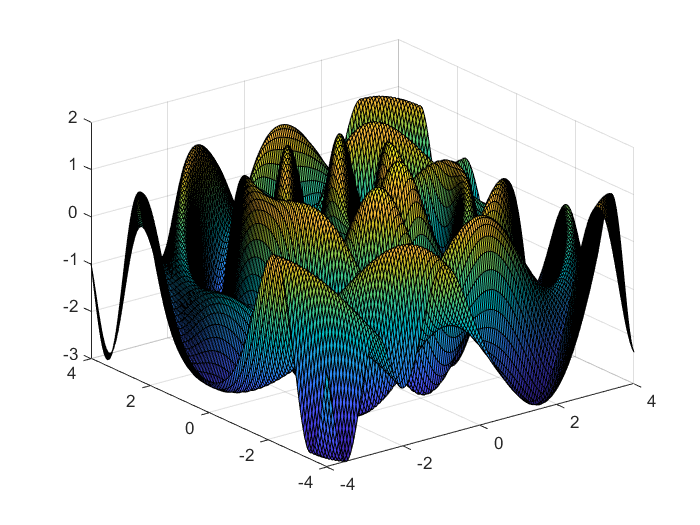

figure;
[X, Y] = meshgrid(x, y);
fkk = 3; % frequency of test function
freq=2*fkk; fk=1;
f1 = @(x,y) sin(freq*sqrt((x-fk).^2+y.^2));%./(freq*sqrt((x-fk).^2+y.^2));
freq=1*fkk; fk=-1;
f2 = @(x,y) -sin(freq*sqrt((x-fk).^2+y.^2));%./(freq*sqrt((x-fk).^2+y.^2));
freq = 0.1*fkk;
f3 = @(x,y) -sin(freq*sqrt(x.^2+y.^2));
ff = @(x,y) f1(x,y)+f2(x,y)+f3(x,y);
Z = ff(X, Y);
%Z = peaks(X, Y);
surf(X, Y, Z);

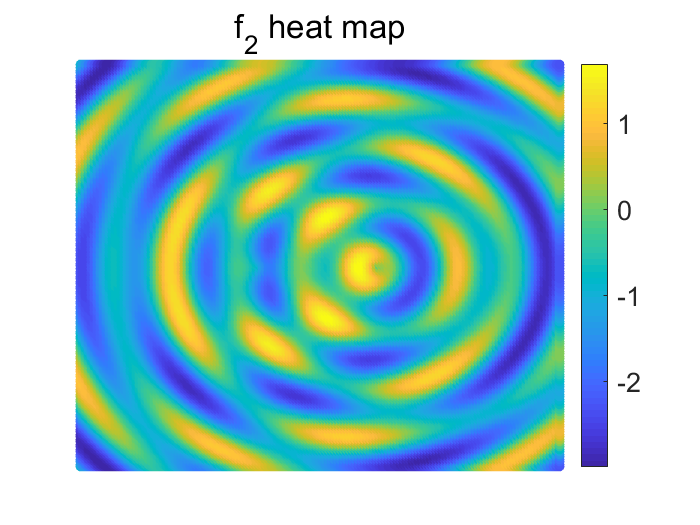

figure;
scatter(X(:), Y(:), [], Z(:), "filled");
axis off
set(gca,'fontsize', 18);
title('f_2 heat map')
colorbar;

xnorm = 1; ynorm = 1; % whether use normalization
yns = 0.1; % noise scale

n = 1e4; % size of training data
ttcs = 300;
ttm = round(n / (ttcs/2));

% represent_ratio = 5;
% dcs = 300; % size of the communication set
% mn = round(n / dcs); % mn is the number of experts (normal)
% m = round(n / (dcs*represent_ratio)); % m is the number of experts (sparse representative)
% lamds = 0:0.5:3.0;

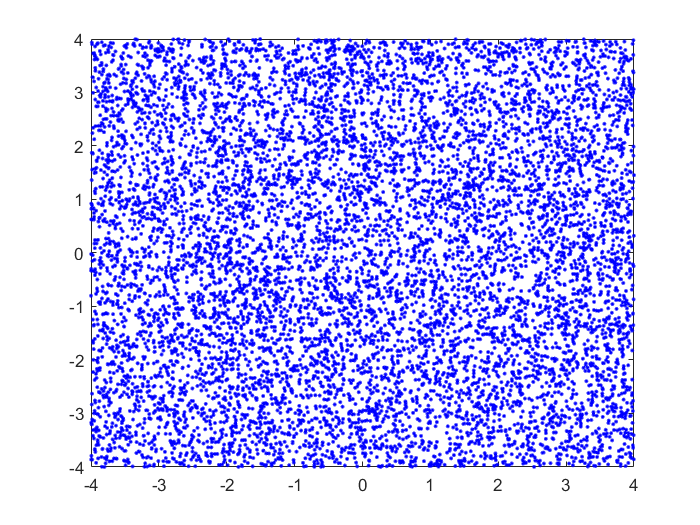

testsize = 2000; % size of test data
valsize = 1000;
induce_step = 100;

% training input
ori_all_trainxs = 8*(rand(n, 1)-0.5);
ori_all_trainys = 8*(rand(n, 1)-0.5);

figure;
plot(ori_all_trainxs, ori_all_trainys, 'b.');

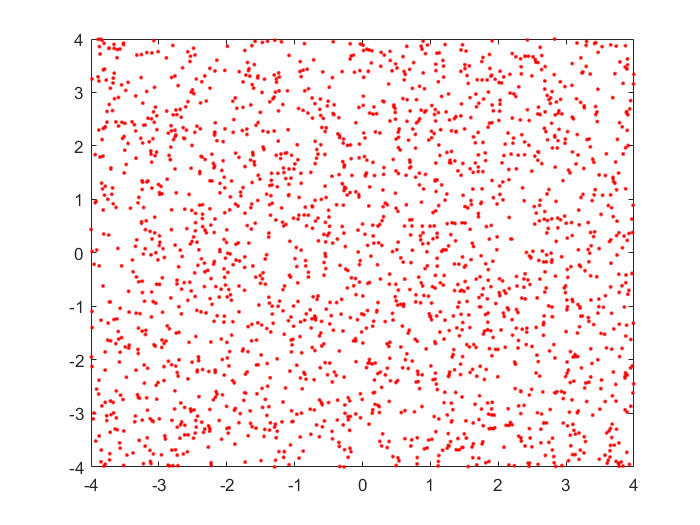


% test input
ori_testxs = 8*(rand(testsize, 1)-0.5);
ori_testys = 8*(rand(testsize, 1)-0.5);

% validation input
ori_valxs = 8*(rand(valsize, 1)-0.5);
ori_valys = 8*(rand(valsize, 1)-0.5);

figure;
plot(ori_testxs, ori_testys, 'r.');


% ininput normalization
if xnorm == 1
    norm_xmean = mean(ori_all_trainxs);
    norm_xstd = std(ori_all_trainxs);
    all_trainxs = (ori_all_trainxs - norm_xmean) / norm_xstd;
    norm_ymean = mean(ori_all_trainys);
    norm_ystd = std(ori_all_trainys);
    all_trainys = (ori_all_trainys - norm_ymean) / norm_ystd;
    
    testxs = (ori_testxs - norm_xmean) / norm_xstd;
    testys = (ori_testys - norm_ymean) / norm_ystd;
    
    valxs = (ori_valxs - norm_xmean) / norm_xstd;
    valys = (ori_valys - norm_ymean) / norm_ystd;
else
    all_trainxs = ori_all_trainxs;
    all_trainys = ori_all_trainys;
    testxs = ori_testxs;
    testys = ori_testys;    
    valxs = ori_valxs;
    valys = ori_valys;    
end

% training output
ln = length(all_trainxs);
xvec = zeros(ln, 2); ori_xvec = zeros(ln, 2);
for i = 1:ln
    xvec(i, :) = [all_trainxs(i), all_trainys(i)];
    ori_xvec(i, :) = [ori_all_trainxs(i), ori_all_trainys(i)];
end
ori_yvec = ff(ori_all_trainxs, ori_all_trainys) + yns*randn(ln, 1);

% test output
ln = length(testxs);
xvec_test = zeros(ln, 2); ori_xvec_test = zeros(ln, 2);
for i = 1:ln
    xvec_test(i, :) = [testxs(i), testys(i)];
    ori_xvec_test(i, :) = [ori_testxs(i), ori_testys(i)];
end
ori_yvec_test = ff(ori_testxs, ori_testys) + yns*randn(ln, 1);

% validation output
ln = length(valxs);
xvec_val = zeros(ln, 2); ori_xvec_val = zeros(ln, 2);
for i = 1:ln
    xvec_val(i, :) = [valxs(i), valys(i)];
    ori_xvec_val(i, :) = [ori_valxs(i), ori_valys(i)];
end
ori_yvec_val = ff(ori_valxs, ori_valys) + yns*randn(ln, 1);

% output normalization
if ynorm == 1
    norm_fmean = mean(ori_yvec);
    norm_fstd = std(ori_yvec);
    all_trainxs = (ori_all_trainxs - norm_xmean) / norm_xstd;
    yvec = (ori_yvec - norm_fmean) / norm_fstd;
    yvec_test = (ori_yvec_test - norm_fmean) / norm_fstd;
    yvec_val = (ori_yvec_val - norm_fmean) / norm_fstd;
else
    yvec = ori_yvec;
    yvec_test = ori_yvec_test;
    yvec_val = ori_yvec_val;
end

store results

kti = 5; % average over kti runs
grls = 0.3:0.05:1.0; % percentage of remaining data to be test
grbcm0_smse_rec = zeros(kti, 1);
rbcm0_smse_rec = zeros(kti, 1);
bcm0_smse_rec = zeros(kti, 1);
gpoe0_smse_rec = zeros(kti, 1);
poe0_smse_rec = zeros(kti, 1);
vfe0_smse_rec = zeros(kti, 1);
spgp0_smse_rec = zeros(kti, 1);
grbcm0_msll_rec = zeros(kti, 1);
rbcm0_msll_rec = zeros(kti, 1);
bcm0_msll_rec = zeros(kti, 1);
gpoe0_msll_rec = zeros(kti, 1);
poe0_msll_rec = zeros(kti, 1);
vfe0_msll_rec = zeros(kti, 1);
spgp0_msll_rec = zeros(kti, 1);
grbcm_gr_smse = zeros(kti, length(grls));
grbcm_gr_msll = zeros(kti, length(grls));
grbcm2_gr_smse = zeros(kti, length(grls));
grbcm2_gr_msll = zeros(kti, length(grls));
grbcm2_spgp_gr_smse = zeros(kti, length(grls));
grbcm2_spgp_gr_msll = zeros(kti, length(grls));

## Experiment I: remove data from the training set

sf2 = 1 ; ell = 1 ; sn2 = 0.1 ; 
d = size(xvec,2);
opts.Xnorm = 'N' ; opts.Ynorm = 'N' ;
opts.Ms = ttm+1;
opts.ell = ell ; opts.sf2 = sf2 ; opts.sn2 = sn2 ;
opts.meanfunc = []; opts.covfunc = @covSEard; opts.likfunc = @likGauss; opts.inffunc = @infGaussLik ;

meanfunc = [];                    % empty: don't use a mean function
covfunc = opts.covfunc;              % Squared Exponental covariance function
likfunc = opts.likfunc;              % Gaussian likelihood
inffunc = opts.inffunc;
km_iters = 1e4;
opts.induce_step = induce_step ;

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 50 ;
opts.Ms = ttm+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, []};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

% default partition
dcs_ecs_r = 0.5;
dcs = round(ttcs*dcs_ecs_r) % size of the communication set

dcs = 150

ecs = ttcs - dcs % size of other experts

ecs = 150

n_per = dcs ; % size of Dc
mn = round(n / ecs); % mn is the number of experts (normal)
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, mn,'MaxIter',km_iters);    

Baselines of VFE and SPGP.

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = mn+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 1;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 

Optimizing hyps in training...
Linesearch      0;  Value 1.514893e+04
Linesearch      1;  Value 9.591731e+03
Linesearch      2;  Value 1.008327e+03
Linesearch      3;  Value 5.366056e+02
Linesearch      4;  Value -5.009841e+03
Linesearch      5;  Value -5.188800e+03
Linesearch      6;  Value -5.290960e+03
Linesearch      7;  Value -5.518916e+03
Linesearch      8;  Value -5.820404e+03
Linesearch      9;  Value -5.865758e+03
Linesearch     10;  Value -5.879238e+03
Linesearch     11;  Value -5.880771e+03
Linesearch     12;  Value -5.881934e+03
Linesearch     13;  Value -5.882696e+03
Linesearch     14;  Value -5.883075e+03
Linesearch     15;  Value -5.883098e+03
Linesearch     16;  Value -5.883102e+03
Linesearch     17;  Value -5.883103e+03
Linesearch     18;  Value -5.883105e+03
Linesearch     19;  Value -5.883105e+03
Linesearch     20;  Value -5.883106e+03
Linesearch     21;  Value -5.883106e+03
Linesearch     22;  Value -5.883106e+03
Linesearch     23;  Value -5.883106e+03
Linesearch   

opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_test,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end

[grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);

GRBCM (Dc size 150): MSE 0.01194456, SMSE 0.01073117, MSLL -2.04631920



g_opts.compute_hyp = 0;

When testing baseline, VFE and SPGP use all partition budget (ttcs = dcs + ecs).

I_com2 = Indics(1:ttcs) ; % randomly select communication set

% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com2, :);
inffunc = @(varargin) infGaussLik(varargin{:}, struct('s', 0.0));
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
[vfe_hyp, tmp_nlzs] = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);

Function evaluation      0;  Value 1.043977e+05
Function evaluation     12;  Value 9.409866e+04
Function evaluation     14;  Value 5.968357e+04
Function evaluation     16;  Value 4.313461e+04
Function evaluation     19;  Value 3.856822e+04
Function evaluation     22;  Value 3.200742e+04
Function evaluation     24;  Value 2.562515e+04
Function evaluation     27;  Value 2.324601e+04
Function evaluation     28;  Value 2.105492e+04
Function evaluation     30;  Value 1.949654e+04
Function evaluation     32;  Value 1.825844e+04
Function evaluation     34;  Value 1.749235e+04
Function evaluation     36;  Value 1.704403e+04
Function evaluation     37;  Value 1.657409e+04
Function evaluation     39;  Value 1.622103e+04
Function evaluation     41;  Value 1.592669e+04
Function evaluation     42;  Value 1.564913e+04
Function evaluation     44;  Value 1.545176e+04
Function evaluation     46;  Value 1.530488e+04
Function evaluation     47;  Value 1.514473e+04
Function evaluation     48;  Value 1.500

vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_test);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE,vfeSMSE,vfeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE baseline', n_per, vfeMSE,vfeSMSE,vfeMSLL);

VFE baseline (Dc size 150): MSE 0.01403693, SMSE 0.01261098, MSLL -1.91573823


% vfe0_smse_rec(ki) = vfeSMSE; vfe0_msll_rec(ki) = vfeMSLL;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

sp_opts = opts;
sp_opts.induce_size = ttcs;
sp_opts.induce_type = 'SPGP_opt';
hyp_init(1:d,1) = -2*opts.hyp.cov(1:d);
hyp_init(d+1,1) = 2*opts.hyp.cov(d+1);
hyp_init(d+2,1) = 2*opts.hyp.lik;

xu = xvec(I_com2, :);
w_init = [reshape(xu,sp_opts.induce_size*d,1);hyp_init];
[w,tmp_nlzs] = minimize(w_init,'spgp_lik_nohyp',-sp_opts.induce_step,yvec,xvec,sp_opts.induce_size);

Function evaluation      0;  Value 3.090109e+02
Function evaluation      9;  Value -2.676229e+02
Function evaluation     11;  Value -6.314090e+02
Function evaluation     13;  Value -1.283239e+03
Function evaluation     15;  Value -1.878377e+03
Function evaluation     16;  Value -2.238519e+03
Function evaluation     18;  Value -2.540664e+03
Function evaluation     19;  Value -2.888074e+03
Function evaluation     21;  Value -3.162569e+03
Function evaluation     23;  Value -3.389267e+03
Function evaluation     25;  Value -3.584066e+03
Function evaluation     27;  Value -3.702786e+03
Function evaluation     29;  Value -3.793048e+03
Function evaluation     30;  Value -3.884369e+03
Function evaluation     32;  Value -3.948634e+03
Function evaluation     34;  Value -4.019338e+03
Function evaluation     36;  Value -4.076558e+03
Function evaluation     37;  Value -4.129050e+03
Function evaluation     39;  Value -4.165458e+03
Function evaluation     41;  Value -4.196223e+03
Function evaluation  

xb = reshape(w(1:sp_opts.induce_size*d,1),sp_opts.induce_size,d);
sp_opts.xu = xb;
sp_opts.sp_hyp = w(sp_opts.induce_size*d+1:end,1);
sp_opts.hyp = opts.hyp;
[tmu,ts2] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,xvec_test,sp_opts.sp_hyp);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[spgpMSE,spgpSMSE,spgpMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'SPSG baseline', n_per, spgpMSE,spgpSMSE,spgpMSLL);

SPSG baseline (Dc size 150): MSE 0.02807007, SMSE 0.02521857, MSLL -1.89692687


% spgp0_smse_rec(ki) = spgpSMSE; spgp0_msll_rec(ki) = spgpMSLL;
[yu,su] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,sp_opts.xu,sp_opts.sp_hyp);
sp_opts.yu = yu; sp_opts.su = su;

Average over 5 runs.

==============1================

Optimizing hyps in training...
Linesearch      0;  Value 1.426666e+04
Linesearch      1;  Value 9.336957e+03
Linesearch      2;  Value 8.431051e+02
Linesearch      3;  Value 2.820384e+02
Linesearch      4;  Value -4.944810e+03
Linesearch      5;  Value -5.147537e+03
Linesearch      6;  Value -5.301380e+03
Linesearch      7;  Value -5.728193e+03
Linesearch      8;  Value -5.843524e+03
Linesearch      9;  Value -5.855129e+03
Linesearch     10;  Value -5.856859e+03
Linesearch     11;  Value -5.859369e+03
Linesearch     12;  Value -5.860839e+03
Linesearch     13;  Value -5.860898e+03
Linesearch     14;  Value -5.860903e+03
Linesearch     15;  Value -5.860904e+03
Linesearch     16;  Value -5.860904e+03
Linesearch     17;  Value -5.860905e+03
Linesearch     18;  Value -5.860905e+03
Linesearch     19;  Value -5.860905e+03
Linesearch     20;  Value -5.860905e+03
Linesearch     21;  Value -5.860905e+03
Linesearch     22;  Value -5.860905e+03
Linesearch     23;  Value -5.860905e+03
Linesearch   

GRBCM (Dc size 150): MSE 0.01172563, SMSE 0.01053448, MSLL -2.06695450


Function evaluation      0;  Value 4.505934e+05
Function evaluation     20;  Value 4.393988e+05
Function evaluation     24;  Value 3.632041e+05
Function evaluation     28;  Value 3.336858e+05
Function evaluation     30;  Value 3.261053e+05
Function evaluation     33;  Value 3.045514e+05
Function evaluation     35;  Value 2.877013e+05
Function evaluation     37;  Value 2.706024e+05
Function evaluation     39;  Value 2.600876e+05
Function evaluation     40;  Value 2.489169e+05
Function evaluation     42;  Value 2.427538e+05
Function evaluation     44;  Value 2.361274e+05
Function evaluation     46;  Value 2.301285e+05
Function evaluation     48;  Value 2.259706e+05
Function evaluation     50;  Value 2.224674e+05
Function evaluation     52;  Value 2.193868e+05
Function evaluation     53;  Value 2.159179e+05
Function evaluation     54;  Value 2.132083e+05
Function evaluation     56;  Value 2.108453e+05
Function evaluation     58;  Value 2.081035e+05
Function evaluation     60;  Value 2.065

VFE (Dc size 150): MSE 0.08042591, SMSE 0.07225584, MSLL -1.10863768


Function evaluation      0;  Value 8.615221e+03
Function evaluation     14;  Value 7.954539e+03
Function evaluation     16;  Value 7.147066e+03
Function evaluation     19;  Value 6.801060e+03
Function evaluation     21;  Value 6.080931e+03
Function evaluation     23;  Value 5.664354e+03
Function evaluation     25;  Value 5.183877e+03
Function evaluation     27;  Value 4.840719e+03
Function evaluation     29;  Value 4.613344e+03
Function evaluation     31;  Value 4.461130e+03
Function evaluation     32;  Value 4.303491e+03
Function evaluation     34;  Value 4.178215e+03
Function evaluation     36;  Value 4.086046e+03
Function evaluation     37;  Value 4.002733e+03
Function evaluation     39;  Value 3.945485e+03
Function evaluation     40;  Value 3.889130e+03
Function evaluation     42;  Value 3.839898e+03
Function evaluation     44;  Value 3.783169e+03
Function evaluation     46;  Value 3.730944e+03
Function evaluation     48;  Value 3.693001e+03
Function evaluation     50;  Value 3.665

SPSG (Dc size 150): MSE 0.15849426, SMSE 0.14239361, MSLL -1.07684218


GRBCM (VFE) (Dc size 150): MSE 0.01164928, SMSE 0.01046589, MSLL -2.11182698


GRBCM (SPGP) (Dc size 150): MSE 0.01169228, SMSE 0.01050451, MSLL -2.10289377


RBCM (Dc size 150): MSE 0.01196550, SMSE 0.0107, MSLL -1.8052


BCM (Dc size 150): MSE 0.01230899, SMSE 0.0111, MSLL -2.2205


PoE (Dc size 150): MSE 0.09443472, SMSE 0.0848, MSLL 3.8836


GPoE (Dc size 150): MSE 0.01187461, SMSE 0.0107, MSLL -1.8069


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

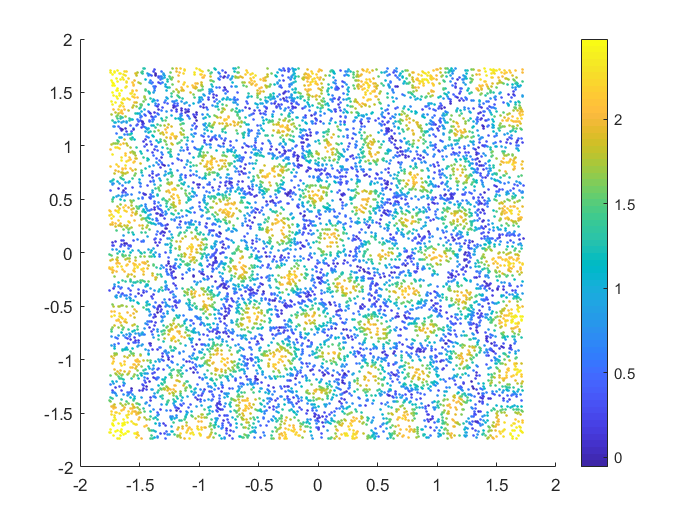

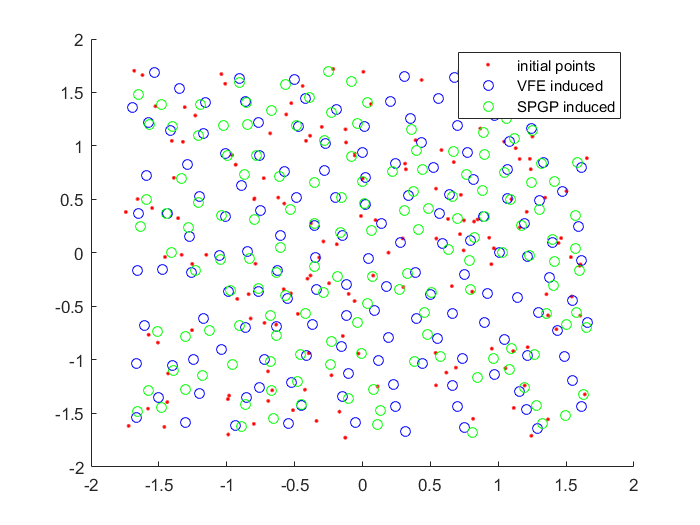

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.03802091, SMSE 0.0342, MSLL -1.7650


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02404988, SMSE 0.0216, MSLL -1.9025


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02489501, SMSE 0.0224, MSLL -1.8908


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.02823575, SMSE 0.0254, MSLL -1.8512


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02121783, SMSE 0.0191, MSLL -1.9663


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02172222, SMSE 0.0195, MSLL -1.9568


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.02375748, SMSE 0.0213, MSLL -1.9011


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01867057, SMSE 0.0168, MSLL -2.0054


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01925549, SMSE 0.0173, MSLL -1.9985


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.02069351, SMSE 0.0186, MSLL -1.9512


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01705732, SMSE 0.0153, MSLL -2.0423


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01712109, SMSE 0.0154, MSLL -2.0381


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01809162, SMSE 0.0163, MSLL -2.0041


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01604061, SMSE 0.0144, MSLL -2.0789


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01575286, SMSE 0.0142, MSLL -2.0820


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01639901, SMSE 0.0147, MSLL -2.0343


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01501805, SMSE 0.0135, MSLL -2.0976


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01447486, SMSE 0.0130, MSLL -2.1083


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01490709, SMSE 0.0134, MSLL -2.0651


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01420645, SMSE 0.0128, MSLL -2.1156


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01399847, SMSE 0.0126, MSLL -2.1170


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01386693, SMSE 0.0125, MSLL -2.0909


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01346957, SMSE 0.0121, MSLL -2.1298


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01364434, SMSE 0.0123, MSLL -2.1187


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01331684, SMSE 0.0120, MSLL -2.0984


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01280239, SMSE 0.0115, MSLL -2.1498


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01296685, SMSE 0.0116, MSLL -2.1384


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01315274, SMSE 0.0118, MSLL -2.0862


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01275284, SMSE 0.0115, MSLL -2.1386


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01299896, SMSE 0.0117, MSLL -2.1190


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01272787, SMSE 0.0114, MSLL -2.0828


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01255101, SMSE 0.0113, MSLL -2.1324


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01268324, SMSE 0.0114, MSLL -2.1139


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01245223, SMSE 0.0112, MSLL -2.0790


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01224547, SMSE 0.0110, MSLL -2.1321


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01232473, SMSE 0.0111, MSLL -2.1164


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01199292, SMSE 0.0108, MSLL -2.0864


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01189973, SMSE 0.0107, MSLL -2.1356


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01196291, SMSE 0.0107, MSLL -2.1202


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01188138, SMSE 0.0107, MSLL -2.0703


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01182995, SMSE 0.0106, MSLL -2.1175


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01186167, SMSE 0.0107, MSLL -2.1059


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01172563, SMSE 0.0105, MSLL -2.0670


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01164928, SMSE 0.0105, MSLL -2.1118


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01169228, SMSE 0.0105, MSLL -2.1029


==============2================

Optimizing hyps in training...
Linesearch      0;  Value 1.444916e+04
Linesearch      1;  Value 9.386262e+03
Linesearch      2;  Value 6.585001e+02
Linesearch      3;  Value 6.431182e+01
Linesearch      4;  Value -4.956066e+03
Linesearch      5;  Value -5.169826e+03
Linesearch      6;  Value -5.602236e+03
Linesearch      7;  Value -5.814159e+03
Linesearch      8;  Value -5.880528e+03
Linesearch      9;  Value -5.887417e+03
Linesearch     10;  Value -5.888584e+03
Linesearch     11;  Value -5.889148e+03
Linesearch     12;  Value -5.889847e+03
Linesearch     13;  Value -5.889972e+03
Linesearch     14;  Value -5.890024e+03
Linesearch     15;  Value -5.890031e+03
Linesearch     16;  Value -5.890033e+03
Linesearch     17;  Value -5.890035e+03
Linesearch     18;  Value -5.890036e+03
Linesearch     19;  Value -5.890036e+03
Linesearch     20;  Value -5.890036e+03
Linesearch     21;  Value -5.890036e+03
Linesearch     22;  Value -5.890036e+03
Linesearch     23;  Value -5.890036e+03
Linesearch   

GRBCM (Dc size 150): MSE 0.01195815, SMSE 0.01074338, MSLL -2.01397980


Function evaluation      0;  Value 4.536107e+05
Function evaluation     17;  Value 4.357326e+05
Function evaluation     19;  Value 3.764044e+05
Function evaluation     22;  Value 3.401485e+05
Function evaluation     25;  Value 3.089513e+05
Function evaluation     27;  Value 2.885467e+05
Function evaluation     29;  Value 2.703042e+05
Function evaluation     31;  Value 2.556791e+05
Function evaluation     33;  Value 2.477159e+05
Function evaluation     34;  Value 2.389489e+05
Function evaluation     36;  Value 2.335224e+05
Function evaluation     37;  Value 2.276805e+05
Function evaluation     39;  Value 2.250578e+05
Function evaluation     41;  Value 2.231022e+05
Function evaluation     43;  Value 2.201958e+05
Function evaluation     44;  Value 2.175262e+05
Function evaluation     46;  Value 2.160835e+05
Function evaluation     48;  Value 2.139468e+05
Function evaluation     50;  Value 2.122865e+05
Function evaluation     52;  Value 2.107884e+05
Function evaluation     54;  Value 2.087

VFE (Dc size 150): MSE 0.10831815, SMSE 0.09731465, MSLL -1.10248528


Function evaluation      0;  Value 8.451065e+03
Function evaluation      9;  Value 8.147864e+03
Function evaluation     11;  Value 7.341941e+03
Function evaluation     13;  Value 6.856384e+03
Function evaluation     15;  Value 6.297188e+03
Function evaluation     16;  Value 5.972830e+03
Function evaluation     18;  Value 5.639324e+03
Function evaluation     20;  Value 5.373101e+03
Function evaluation     21;  Value 5.118634e+03
Function evaluation     23;  Value 4.971459e+03
Function evaluation     25;  Value 4.785635e+03
Function evaluation     26;  Value 4.604961e+03
Function evaluation     28;  Value 4.448009e+03
Function evaluation     30;  Value 4.328221e+03
Function evaluation     32;  Value 4.263366e+03
Function evaluation     33;  Value 4.191963e+03
Function evaluation     35;  Value 4.096453e+03
Function evaluation     37;  Value 4.016314e+03
Function evaluation     39;  Value 3.957116e+03
Function evaluation     41;  Value 3.911625e+03
Function evaluation     43;  Value 3.856

SPSG (Dc size 150): MSE 0.17101853, SMSE 0.15364560, MSLL -1.09171269


GRBCM (VFE) (Dc size 150): MSE 0.01181869, SMSE 0.01061809, MSLL -2.09521551


GRBCM (SPGP) (Dc size 150): MSE 0.01175277, SMSE 0.01055886, MSLL -2.08620979


RBCM (Dc size 150): MSE 0.01218529, SMSE 0.0109, MSLL -1.7726


BCM (Dc size 150): MSE 0.01249961, SMSE 0.0112, MSLL -2.2050


PoE (Dc size 150): MSE 0.10268905, SMSE 0.0923, MSLL 4.6703


GPoE (Dc size 150): MSE 0.01221013, SMSE 0.0110, MSLL -1.7530


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.03446682, SMSE 0.0310, MSLL -1.7938


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02183968, SMSE 0.0196, MSLL -1.9488


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02225236, SMSE 0.0200, MSLL -1.9235


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.02538968, SMSE 0.0228, MSLL -1.8871


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01884228, SMSE 0.0169, MSLL -2.0071


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01988925, SMSE 0.0179, MSLL -1.9757


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.02226980, SMSE 0.0200, MSLL -1.9291


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01773210, SMSE 0.0159, MSLL -2.0451


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01803864, SMSE 0.0162, MSLL -2.0235


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01911881, SMSE 0.0172, MSLL -1.9908


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01645857, SMSE 0.0148, MSLL -2.0831


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01659627, SMSE 0.0149, MSLL -2.0672


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01758823, SMSE 0.0158, MSLL -2.0089


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01548590, SMSE 0.0139, MSLL -2.1036


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01560160, SMSE 0.0140, MSLL -2.0869


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01613889, SMSE 0.0145, MSLL -2.0390


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01457448, SMSE 0.0131, MSLL -2.1270


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01438594, SMSE 0.0129, MSLL -2.1242


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01464278, SMSE 0.0132, MSLL -2.0719


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01384114, SMSE 0.0124, MSLL -2.1431


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01381176, SMSE 0.0124, MSLL -2.1374


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01350580, SMSE 0.0121, MSLL -2.0956


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01294306, SMSE 0.0116, MSLL -2.1657


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01297714, SMSE 0.0117, MSLL -2.1506


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01298525, SMSE 0.0117, MSLL -2.0966


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01276897, SMSE 0.0115, MSLL -2.1603


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01281554, SMSE 0.0115, MSLL -2.1419


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01278875, SMSE 0.0115, MSLL -2.0811


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01261766, SMSE 0.0113, MSLL -2.1465


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01266732, SMSE 0.0114, MSLL -2.1279


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01247461, SMSE 0.0112, MSLL -2.0667


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01243300, SMSE 0.0112, MSLL -2.1326


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01243696, SMSE 0.0112, MSLL -2.1132


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01232257, SMSE 0.0111, MSLL -2.0528


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01221458, SMSE 0.0110, MSLL -2.1316


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01215209, SMSE 0.0109, MSLL -2.1144


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01222423, SMSE 0.0110, MSLL -2.0333


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01212136, SMSE 0.0109, MSLL -2.1087


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01208131, SMSE 0.0109, MSLL -2.0952


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01200543, SMSE 0.0108, MSLL -2.0272


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01190662, SMSE 0.0107, MSLL -2.1090


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01189820, SMSE 0.0107, MSLL -2.0897


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01195815, SMSE 0.0107, MSLL -2.0140


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01181869, SMSE 0.0106, MSLL -2.0952


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01175277, SMSE 0.0106, MSLL -2.0862


==============3================

Optimizing hyps in training...
Linesearch      0;  Value 1.505384e+04
Linesearch      1;  Value 9.567417e+03
Linesearch      2;  Value 6.544292e+02
Linesearch      3;  Value 2.393672e+01
Linesearch      4;  Value -4.875612e+03
Linesearch      5;  Value -5.182447e+03
Linesearch      6;  Value -5.279436e+03
Linesearch      7;  Value -5.486112e+03
Linesearch      8;  Value -5.829361e+03
Linesearch      9;  Value -5.880189e+03
Linesearch     10;  Value -5.899879e+03
Linesearch     11;  Value -5.900717e+03
Linesearch     12;  Value -5.902174e+03
Linesearch     13;  Value -5.902746e+03
Linesearch     14;  Value -5.902831e+03
Linesearch     15;  Value -5.902838e+03
Linesearch     16;  Value -5.902838e+03
Linesearch     17;  Value -5.902838e+03
Linesearch     18;  Value -5.902838e+03
Linesearch     19;  Value -5.902838e+03
Linesearch     20;  Value -5.902838e+03
Linesearch     21;  Value -5.902838e+03
Linesearch     22;  Value -5.902838e+03
Linesearch     23;  Value -5.902838e+03
Linesearch   

GRBCM (Dc size 150): MSE 0.01196406, SMSE 0.01074869, MSLL -2.01800756


Function evaluation      0;  Value 4.748386e+05
Function evaluation     14;  Value 4.018706e+05
Function evaluation     20;  Value 3.598953e+05
Function evaluation     22;  Value 3.503557e+05
Function evaluation     25;  Value 3.203713e+05
Function evaluation     27;  Value 2.865523e+05
Function evaluation     30;  Value 2.719933e+05
Function evaluation     31;  Value 2.569471e+05
Function evaluation     33;  Value 2.445929e+05
Function evaluation     35;  Value 2.330227e+05
Function evaluation     37;  Value 2.246474e+05
Function evaluation     39;  Value 2.191468e+05
Function evaluation     41;  Value 2.147156e+05
Function evaluation     43;  Value 2.107777e+05
Function evaluation     45;  Value 2.085263e+05
Function evaluation     47;  Value 2.054717e+05
Function evaluation     49;  Value 2.031486e+05
Function evaluation     51;  Value 2.017933e+05
Function evaluation     53;  Value 2.007113e+05
Function evaluation     55;  Value 1.993983e+05
Function evaluation     57;  Value 1.983

VFE (Dc size 150): MSE 0.08820018, SMSE 0.07924035, MSLL -1.11115774


Function evaluation      0;  Value 8.559161e+03
Function evaluation     10;  Value 7.551960e+03
Function evaluation     18;  Value 7.130636e+03
Function evaluation     21;  Value 6.624339e+03
Function evaluation     23;  Value 6.272498e+03
Function evaluation     24;  Value 5.743157e+03
Function evaluation     26;  Value 5.376038e+03
Function evaluation     28;  Value 5.128521e+03
Function evaluation     30;  Value 4.903643e+03
Function evaluation     32;  Value 4.770005e+03
Function evaluation     33;  Value 4.626269e+03
Function evaluation     35;  Value 4.514055e+03
Function evaluation     36;  Value 4.396472e+03
Function evaluation     38;  Value 4.305283e+03
Function evaluation     40;  Value 4.187415e+03
Function evaluation     42;  Value 4.101512e+03
Function evaluation     44;  Value 4.041397e+03
Function evaluation     46;  Value 3.972600e+03
Function evaluation     48;  Value 3.925758e+03
Function evaluation     49;  Value 3.881641e+03
Function evaluation     50;  Value 3.834

SPSG (Dc size 150): MSE 0.20853875, SMSE 0.18735432, MSLL -1.11060237


GRBCM (VFE) (Dc size 150): MSE 0.01185004, SMSE 0.01064625, MSLL -2.07041622


GRBCM (SPGP) (Dc size 150): MSE 0.01174659, SMSE 0.01055331, MSLL -2.07619676


RBCM (Dc size 150): MSE 0.01189211, SMSE 0.0107, MSLL -1.8093


BCM (Dc size 150): MSE 0.01228173, SMSE 0.0110, MSLL -2.2227


PoE (Dc size 150): MSE 0.09660415, SMSE 0.0868, MSLL 4.0535


GPoE (Dc size 150): MSE 0.01187685, SMSE 0.0107, MSLL -1.7986


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.03623360, SMSE 0.0326, MSLL -1.7645


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02275566, SMSE 0.0204, MSLL -1.9211


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02322467, SMSE 0.0209, MSLL -1.9323


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.02838956, SMSE 0.0255, MSLL -1.8574


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01963122, SMSE 0.0176, MSLL -1.9878


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01958823, SMSE 0.0176, MSLL -1.9895


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.02314256, SMSE 0.0208, MSLL -1.9262


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01782820, SMSE 0.0160, MSLL -2.0405


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01741111, SMSE 0.0156, MSLL -2.0350


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.02025490, SMSE 0.0182, MSLL -1.9740


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01653493, SMSE 0.0149, MSLL -2.0770


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01627736, SMSE 0.0146, MSLL -2.0711


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01812104, SMSE 0.0163, MSLL -2.0103


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01576439, SMSE 0.0142, MSLL -2.0971


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01547517, SMSE 0.0139, MSLL -2.0917


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01640594, SMSE 0.0147, MSLL -2.0393


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01475320, SMSE 0.0133, MSLL -2.1144


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01486537, SMSE 0.0134, MSLL -2.0949


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01527336, SMSE 0.0137, MSLL -2.0510


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01390148, SMSE 0.0125, MSLL -2.1338


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01396084, SMSE 0.0125, MSLL -2.1116


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01415870, SMSE 0.0127, MSLL -2.0658


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01312247, SMSE 0.0118, MSLL -2.1459


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01313498, SMSE 0.0118, MSLL -2.1309


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01372573, SMSE 0.0123, MSLL -2.0600


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01287062, SMSE 0.0116, MSLL -2.1405


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01284139, SMSE 0.0115, MSLL -2.1259


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01314646, SMSE 0.0118, MSLL -2.0634


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01263282, SMSE 0.0113, MSLL -2.1287


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01247930, SMSE 0.0112, MSLL -2.1218


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01262302, SMSE 0.0113, MSLL -2.0638


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01236220, SMSE 0.0111, MSLL -2.1251


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01223071, SMSE 0.0110, MSLL -2.1204


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01247962, SMSE 0.0112, MSLL -2.0499


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01215675, SMSE 0.0109, MSLL -2.1158


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01218114, SMSE 0.0109, MSLL -2.1003


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01218132, SMSE 0.0109, MSLL -2.0506


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01198098, SMSE 0.0108, MSLL -2.1072


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01198217, SMSE 0.0108, MSLL -2.0989


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01205797, SMSE 0.0108, MSLL -2.0276


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01189529, SMSE 0.0107, MSLL -2.0852


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01183704, SMSE 0.0106, MSLL -2.0845


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01196406, SMSE 0.0107, MSLL -2.0180


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01185004, SMSE 0.0106, MSLL -2.0704


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01174659, SMSE 0.0106, MSLL -2.0762


==============4================

Optimizing hyps in training...
Linesearch      0;  Value 1.565467e+04
Linesearch      1;  Value 9.736418e+03
Linesearch      2;  Value 6.814167e+02
Linesearch      3;  Value 1.397998e+02
Linesearch      4;  Value -5.008644e+03
Linesearch      5;  Value -5.233680e+03
Linesearch      6;  Value -5.321393e+03
Linesearch      7;  Value -5.521026e+03
Linesearch      8;  Value -5.799991e+03
Linesearch      9;  Value -5.873890e+03
Linesearch     10;  Value -5.885955e+03
Linesearch     11;  Value -5.888980e+03
Linesearch     12;  Value -5.894184e+03
Linesearch     13;  Value -5.895648e+03
Linesearch     14;  Value -5.895648e+03
Linesearch     15;  Value -5.895649e+03
Linesearch     16;  Value -5.895650e+03
Linesearch     17;  Value -5.895650e+03
Linesearch     18;  Value -5.895650e+03
Linesearch     19;  Value -5.895650e+03
Linesearch     20;  Value -5.895650e+03
Linesearch     21;  Value -5.895650e+03
Linesearch     22;  Value -5.895650e+03


GRBCM (Dc size 150): MSE 0.01217717, SMSE 0.01094015, MSLL -2.00467919


Function evaluation      0;  Value 4.801970e+05
Function evaluation     20;  Value 4.046670e+05
Function evaluation     22;  Value 3.529593e+05
Function evaluation     25;  Value 3.406056e+05
Function evaluation     27;  Value 3.239685e+05
Function evaluation     29;  Value 2.979557e+05
Function evaluation     31;  Value 2.800586e+05
Function evaluation     33;  Value 2.702228e+05
Function evaluation     35;  Value 2.575403e+05
Function evaluation     37;  Value 2.483187e+05
Function evaluation     38;  Value 2.388547e+05
Function evaluation     40;  Value 2.329330e+05
Function evaluation     42;  Value 2.288227e+05
Function evaluation     43;  Value 2.245643e+05
Function evaluation     45;  Value 2.214203e+05
Function evaluation     46;  Value 2.179326e+05
Function evaluation     48;  Value 2.160095e+05
Function evaluation     50;  Value 2.138234e+05
Function evaluation     52;  Value 2.118103e+05
Function evaluation     54;  Value 2.092475e+05
Function evaluation     56;  Value 2.075

VFE (Dc size 150): MSE 0.08492627, SMSE 0.07629903, MSLL -1.09895602


Function evaluation      0;  Value 9.176698e+03
Function evaluation     19;  Value 7.558707e+03
Function evaluation     23;  Value 7.167834e+03
Function evaluation     26;  Value 6.498872e+03
Function evaluation     27;  Value 6.128718e+03
Function evaluation     29;  Value 5.658701e+03
Function evaluation     31;  Value 5.311499e+03
Function evaluation     33;  Value 5.013407e+03
Function evaluation     35;  Value 4.796584e+03
Function evaluation     36;  Value 4.709402e+03
Function evaluation     37;  Value 4.513974e+03
Function evaluation     38;  Value 4.306162e+03
Function evaluation     40;  Value 4.130651e+03
Function evaluation     41;  Value 3.967741e+03
Function evaluation     43;  Value 3.878914e+03
Function evaluation     44;  Value 3.779870e+03
Function evaluation     45;  Value 3.690486e+03
Function evaluation     47;  Value 3.610116e+03
Function evaluation     48;  Value 3.526583e+03
Function evaluation     50;  Value 3.481456e+03
Function evaluation     51;  Value 3.436

SPSG (Dc size 150): MSE 0.15535826, SMSE 0.13957618, MSLL -1.10775617


GRBCM (VFE) (Dc size 150): MSE 0.01166735, SMSE 0.01048212, MSLL -2.09381373


GRBCM (SPGP) (Dc size 150): MSE 0.01165665, SMSE 0.01047251, MSLL -2.11163624


RBCM (Dc size 150): MSE 0.01211432, SMSE 0.0109, MSLL -1.7714


BCM (Dc size 150): MSE 0.01259098, SMSE 0.0113, MSLL -2.1973


PoE (Dc size 150): MSE 0.10116991, SMSE 0.0909, MSLL 4.5106


GPoE (Dc size 150): MSE 0.01209238, SMSE 0.0109, MSLL -1.7601


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.03667155, SMSE 0.0329, MSLL -1.7936


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02019413, SMSE 0.0181, MSLL -1.9487


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02178315, SMSE 0.0196, MSLL -1.9445


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.03229905, SMSE 0.0290, MSLL -1.8325


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02105571, SMSE 0.0189, MSLL -1.9753


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02125684, SMSE 0.0191, MSLL -1.9787


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.02781187, SMSE 0.0250, MSLL -1.8811


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01858508, SMSE 0.0167, MSLL -2.0303


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01999398, SMSE 0.0180, MSLL -2.0154


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.02351944, SMSE 0.0211, MSLL -1.9409


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01718783, SMSE 0.0154, MSLL -2.0675


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01792712, SMSE 0.0161, MSLL -2.0618


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01927899, SMSE 0.0173, MSLL -1.9891


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01586740, SMSE 0.0143, MSLL -2.0844


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01589025, SMSE 0.0143, MSLL -2.0891


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01676823, SMSE 0.0151, MSLL -2.0367


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01475222, SMSE 0.0133, MSLL -2.1114


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01456498, SMSE 0.0131, MSLL -2.1191


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01537908, SMSE 0.0138, MSLL -2.0548


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01393915, SMSE 0.0125, MSLL -2.1321


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01402920, SMSE 0.0126, MSLL -2.1206


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01481765, SMSE 0.0133, MSLL -2.0498


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01345841, SMSE 0.0121, MSLL -2.1332


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01339112, SMSE 0.0120, MSLL -2.1285


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01371856, SMSE 0.0123, MSLL -2.0709


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01293609, SMSE 0.0116, MSLL -2.1409


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01270848, SMSE 0.0114, MSLL -2.1464


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01337078, SMSE 0.0120, MSLL -2.0667


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01268965, SMSE 0.0114, MSLL -2.1354


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01243284, SMSE 0.0112, MSLL -2.1465


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01302682, SMSE 0.0117, MSLL -2.0606


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01243839, SMSE 0.0112, MSLL -2.1285


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01220774, SMSE 0.0110, MSLL -2.1460


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01241926, SMSE 0.0112, MSLL -2.0689


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01200297, SMSE 0.0108, MSLL -2.1336


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01182333, SMSE 0.0106, MSLL -2.1501


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01214732, SMSE 0.0109, MSLL -2.0627


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01175437, SMSE 0.0106, MSLL -2.1295


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01163558, SMSE 0.0105, MSLL -2.1482


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01218780, SMSE 0.0109, MSLL -2.0273


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01171632, SMSE 0.0105, MSLL -2.1097


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01170307, SMSE 0.0105, MSLL -2.1231


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01217717, SMSE 0.0109, MSLL -2.0047


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01166735, SMSE 0.0105, MSLL -2.0938


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01165665, SMSE 0.0105, MSLL -2.1116


==============5================

Optimizing hyps in training...
Linesearch      0;  Value 1.516349e+04
Linesearch      1;  Value 9.615361e+03
Linesearch      2;  Value 8.085738e+02
Linesearch      3;  Value 2.506699e+02
Linesearch      4;  Value -4.954405e+03
Linesearch      5;  Value -5.160917e+03
Linesearch      6;  Value -5.369256e+03
Linesearch      7;  Value -5.752272e+03
Linesearch      8;  Value -5.873357e+03
Linesearch      9;  Value -5.877073e+03
Linesearch     10;  Value -5.879312e+03
Linesearch     11;  Value -5.882820e+03
Linesearch     12;  Value -5.885232e+03
Linesearch     13;  Value -5.885277e+03
Linesearch     14;  Value -5.885284e+03
Linesearch     15;  Value -5.885285e+03
Linesearch     16;  Value -5.885287e+03
Linesearch     17;  Value -5.885287e+03
Linesearch     18;  Value -5.885287e+03
Linesearch     19;  Value -5.885287e+03
Linesearch     20;  Value -5.885287e+03
Linesearch     21;  Value -5.885287e+03
Linesearch     22;  Value -5.885287e+03
Linesearch     23;  Value -5.885287e+03


GRBCM (Dc size 150): MSE 0.01195039, SMSE 0.01073641, MSLL -2.03962653


Function evaluation      0;  Value 4.528892e+05
Function evaluation     11;  Value 4.453990e+05
Function evaluation     12;  Value 4.380699e+05
Function evaluation     15;  Value 3.803871e+05
Function evaluation     17;  Value 3.410258e+05
Function evaluation     19;  Value 3.086824e+05
Function evaluation     21;  Value 2.806371e+05
Function evaluation     23;  Value 2.675512e+05
Function evaluation     25;  Value 2.569464e+05
Function evaluation     27;  Value 2.444878e+05
Function evaluation     29;  Value 2.368295e+05
Function evaluation     30;  Value 2.301019e+05
Function evaluation     32;  Value 2.249293e+05
Function evaluation     34;  Value 2.205749e+05
Function evaluation     36;  Value 2.175336e+05
Function evaluation     37;  Value 2.142961e+05
Function evaluation     39;  Value 2.117575e+05
Function evaluation     41;  Value 2.097364e+05
Function evaluation     43;  Value 2.080378e+05
Function evaluation     45;  Value 2.060634e+05
Function evaluation     47;  Value 2.049

VFE (Dc size 150): MSE 0.09548850, SMSE 0.08578829, MSLL -1.08399580


Function evaluation      0;  Value 8.558743e+03
Function evaluation     10;  Value 7.804210e+03
Function evaluation     12;  Value 6.949061e+03
Function evaluation     14;  Value 6.309153e+03
Function evaluation     16;  Value 5.974922e+03
Function evaluation     18;  Value 5.763835e+03
Function evaluation     19;  Value 5.537288e+03
Function evaluation     21;  Value 5.292204e+03
Function evaluation     23;  Value 5.143255e+03
Function evaluation     25;  Value 4.944884e+03
Function evaluation     26;  Value 4.748552e+03
Function evaluation     27;  Value 4.576369e+03
Function evaluation     29;  Value 4.491134e+03
Function evaluation     30;  Value 4.397877e+03
Function evaluation     32;  Value 4.296903e+03
Function evaluation     34;  Value 4.214909e+03
Function evaluation     35;  Value 4.130701e+03
Function evaluation     37;  Value 4.063390e+03
Function evaluation     39;  Value 4.021743e+03
Function evaluation     40;  Value 3.979304e+03
Function evaluation     42;  Value 3.924

SPSG (Dc size 150): MSE 0.13861333, SMSE 0.12453229, MSLL -1.09108737


GRBCM (VFE) (Dc size 150): MSE 0.01176017, SMSE 0.01056551, MSLL -2.10075918


GRBCM (SPGP) (Dc size 150): MSE 0.01166815, SMSE 0.01048284, MSLL -2.08165763


RBCM (Dc size 150): MSE 0.01216250, SMSE 0.0109, MSLL -1.7755


BCM (Dc size 150): MSE 0.01276918, SMSE 0.0115, MSLL -2.1903


PoE (Dc size 150): MSE 0.10103713, SMSE 0.0908, MSLL 4.5045


GPoE (Dc size 150): MSE 0.01213032, SMSE 0.0109, MSLL -1.7646


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.03415921, SMSE 0.0307, MSLL -1.8041


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02296870, SMSE 0.0206, MSLL -1.9197


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02438858, SMSE 0.0219, MSLL -1.9110


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.02738856, SMSE 0.0246, MSLL -1.8672


GRBCM++ (VFE) (Dc size 150): 
MSE 0.02116914, SMSE 0.0190, MSLL -1.9676


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.02061068, SMSE 0.0185, MSLL -1.9654


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.02218323, SMSE 0.0199, MSLL -1.9351


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01789279, SMSE 0.0161, MSLL -2.0312


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01797282, SMSE 0.0161, MSLL -2.0158


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01913175, SMSE 0.0172, MSLL -1.9951


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01596187, SMSE 0.0143, MSLL -2.0860


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01610888, SMSE 0.0145, MSLL -2.0703


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01657046, SMSE 0.0149, MSLL -2.0512


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01492240, SMSE 0.0134, MSLL -2.1203


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01459078, SMSE 0.0131, MSLL -2.1116


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01503855, SMSE 0.0135, MSLL -2.0863


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01369683, SMSE 0.0123, MSLL -2.1596


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01353569, SMSE 0.0122, MSLL -2.1418


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01440895, SMSE 0.0129, MSLL -2.0993


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01376001, SMSE 0.0124, MSLL -2.1532


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01334786, SMSE 0.0120, MSLL -2.1403


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01368246, SMSE 0.0123, MSLL -2.1045


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01310295, SMSE 0.0118, MSLL -2.1602


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01301808, SMSE 0.0117, MSLL -2.1391


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01318951, SMSE 0.0118, MSLL -2.1056


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01275745, SMSE 0.0115, MSLL -2.1545


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01271688, SMSE 0.0114, MSLL -2.1341


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01298532, SMSE 0.0117, MSLL -2.0971


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01255840, SMSE 0.0113, MSLL -2.1490


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01250969, SMSE 0.0112, MSLL -2.1292


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01232110, SMSE 0.0111, MSLL -2.1174


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01208703, SMSE 0.0109, MSLL -2.1587


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01194638, SMSE 0.0107, MSLL -2.1456


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01218807, SMSE 0.0109, MSLL -2.0984


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01194362, SMSE 0.0107, MSLL -2.1421


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01183894, SMSE 0.0106, MSLL -2.1295


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01197369, SMSE 0.0108, MSLL -2.0898


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01177533, SMSE 0.0106, MSLL -2.1357


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01168794, SMSE 0.0105, MSLL -2.1221


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01192180, SMSE 0.0107, MSLL -2.0675


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01175136, SMSE 0.0106, MSLL -2.1179


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01164143, SMSE 0.0105, MSLL -2.1036


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01195039, SMSE 0.0107, MSLL -2.0396


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01176017, SMSE 0.0106, MSLL -2.1008


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01166815, SMSE 0.0105, MSLL -2.0817


kti = 5;
m = mn;

for ki=1:kti
fprintf("==============%d================", ki)
n_per = dcs ; % size of Dc
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, m,'MaxIter',km_iters);    

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = m+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 1;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 
opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_test,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[grbcmMSE_bl,grbcmSMSE_bl,grbcmMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE_bl,grbcmSMSE_bl,grbcmMSLL_bl);
grbcm0_smse_rec(ki) = grbcmSMSE_bl; grbcm0_msll_rec(ki) = grbcmMSLL_bl;
g_opts.compute_hyp = 0;


% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com, :);
inffunc = @(varargin) infGaussLik(varargin{:}, struct('s', 0.0));
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
vfe_hyp = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);
vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_test);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE_bl,vfeSMSE_bl,vfeMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE', n_per, vfeMSE_bl,vfeSMSE_bl,vfeMSLL_bl);
vfe0_smse_rec(ki) = vfeSMSE_bl; vfe0_msll_rec(ki) = vfeMSLL_bl;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

sp_opts = opts;
sp_opts.induce_type = 'SPGP_opt';
hyp_init(1:d,1) = -2*opts.hyp.cov(1:d);
hyp_init(d+1,1) = 2*opts.hyp.cov(d+1);
hyp_init(d+2,1) = 2*opts.hyp.lik;

xu = xvec(I_com, :);
w_init = [reshape(xu,sp_opts.induce_size*d,1);hyp_init];
[w,f] = minimize(w_init,'spgp_lik_nohyp',-sp_opts.induce_step,yvec,xvec,sp_opts.induce_size);
xb = reshape(w(1:sp_opts.induce_size*d,1),sp_opts.induce_size,d);
sp_opts.xu = xb;
sp_opts.sp_hyp = w(sp_opts.induce_size*d+1:end,1);
sp_opts.hyp = opts.hyp;

[tmu,ts2] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,xvec_test,sp_opts.sp_hyp);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[spgpMSE_bl,spgpSMSE_bl,spgpMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'SPSG', n_per, spgpMSE_bl,spgpSMSE_bl,spgpMSLL_bl);
spgp0_smse_rec(ki) = spgpSMSE_bl; spgp0_msll_rec(ki) = spgpMSLL_bl;
[yu,su] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,sp_opts.xu,sp_opts.sp_hyp);
sp_opts.yu = yu; sp_opts.su = su;

vfe_opts.grbcm_baseline = 0;
vfe_opts.global_index = ones(n,1);
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM (VFE)', n_per, MSE,SMSE,MSLL);

sp_opts.grbcm_baseline = 0;
sp_opts.global_index = ones(n,1);
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM (SPGP)', n_per, MSE,SMSE,MSLL);


criterion = 'RBCM';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[rbcmMSE,rbcmSMSE,rbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, rbcmMSE,rbcmSMSE,rbcmMSLL);
rbcm0_smse_rec(ki) = rbcmSMSE; rbcm0_msll_rec(ki) = rbcmMSLL;

criterion = 'BCM';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[bcmMSE,bcmSMSE,bcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, bcmMSE,bcmSMSE,bcmMSLL);
bcm0_smse_rec(ki) = bcmSMSE; bcm0_msll_rec(ki) = bcmMSLL;

criterion = 'PoE';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[poeMSE,poeSMSE,poeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, poeMSE,poeSMSE,poeMSLL);
poe0_smse_rec(ki) = poeSMSE; poe0_msll_rec(ki) = poeMSLL;

criterion = 'GPoE';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[gpoeMSE,gpoeSMSE,gpoeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, gpoeMSE,gpoeSMSE,gpoeMSLL);
gpoe0_smse_rec(ki) = gpoeSMSE; gpoe0_msll_rec(ki) = gpoeMSLL;

% compute informatic importance
ds = zeros(n, m);
for i=1:n
    for j=1:m
        %ds(i,j) = muti1(i)-muti2(j,i)+muti1(j)-muti2(i,j);
        ds(i,j) = norm(xvec(i, :) - C(j,:));
    end
end
% 1st closest cluster centers
[~, fcc] = min(ds, [], 2);
% set to inf
for i=1:n
    ds(i, fcc(i)) = 1e10;
end
% 2st closest cluster centers
[~, scc] = min(ds, [], 2);
rk = zeros(n, 1);
for iik=1:n
    if mod(iik, 1e2)==0
        fprintf('processing distance: %d/%d\n', iik, n);
    end
    i = fcc(iik);
    [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
        covfunc,likfunc,models{i+1}.X,models{i+1}.Y,xvec(iik,:));
    h1 = 0.5*log(tmp_sig2);
    j = scc(iik);
%     [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
%         covfunc,likfunc,[models{i+1}.X;models{j+1}.X],[models{i+1}.Y;models{j+1}.Y],xvec(iik,:));
    [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
        covfunc,likfunc,[models{j+1}.X],[models{j+1}.Y],xvec(iik,:));
    h2 = 0.5*log(tmp_sig2);
    rk(iik) = h2 - h1; % importance is the difference between mutual information
end

if ki==1
    figure;
    scatter(xvec(:,1), xvec(:,2), 3, rk, "filled"); colorbar;
    figure; hold on;
    plot(xvec(I_com,1), xvec(I_com,2), 'r.');
    plot(vfe_opts.xu(:,1), vfe_opts.xu(:,2), 'bo');
    plot(sp_opts.xu(:,1), sp_opts.xu(:,2), 'go');
    legend('initial points', 'VFE induced', 'SPGP induced'); 
end

for kj=1:length(grls) % test/validate different remaining percentage
    kj
    gr=grls(kj)
    crk = rk;
    crk(I_com) = -1e10;
    [~, crk_idx] = sort(crk, 'descend');
    rn = round(n*gr);
    global_index = zeros(n,1);
    global_index(crk_idx(1:rn)) = 1; % select remaining data according to the importance
    
    % only remove data from subsets, in RBGCM
    g_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,g_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);
    grbcm_gr_smse(ki,kj) = grbcmSMSE; grbcm_gr_msll(ki,kj) = grbcmMSLL;

    vfe_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (VFE)', n_per, MSE,SMSE,MSLL);
    grbcm2_gr_smse(ki,kj) = SMSE; grbcm2_gr_msll(ki,kj) = MSLL;
    
    sp_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (SPGP)', n_per, MSE,SMSE,MSLL);
    grbcm2_spgp_gr_smse(ki,kj) = SMSE; grbcm2_spgp_gr_msll(ki,kj) = MSLL;
end   
end

Display results

grbcm0_smse = mean(grbcm0_smse_rec(1:kti)); grbcm0_msll = mean(grbcm0_msll_rec(1:kti));
rbcm0_smse = mean(rbcm0_smse_rec(1:kti)); rbcm0_msll = mean(rbcm0_msll_rec(1:kti));
bcm0_smse = mean(bcm0_smse_rec(1:kti)); bcm0_msll = mean(bcm0_msll_rec(1:kti));
poe0_smse = mean(poe0_smse_rec(1:kti)); poe0_msll = mean(poe0_msll_rec(1:kti));
gpoe0_smse = mean(gpoe0_smse_rec(1:kti)); gpoe0_msll = mean(gpoe0_msll_rec(1:kti));
vfe0_smse = mean(vfe0_smse_rec(1:kti)); vfe0_msll = mean(vfe0_msll_rec(1:kti));
spgp0_smse = mean(spgp0_smse_rec(1:kti)); spgp0_msll = mean(spgp0_msll_rec(1:kti));

fprintf('GRBCM: %6.8f, %6.4f', grbcm0_smse, grbcm0_msll);

GRBCM: 0.01074062, -2.0286

fprintf('RBCM: %6.8f, %6.4f', rbcm0_smse, rbcm0_msll);

RBCM: 0.01083843, -1.7868

fprintf('BCM: %6.8f, %6.4f', bcm0_smse, bcm0_msll);

BCM: 0.01122129, -2.2072

fprintf('GPoE: %6.8f, %6.4f', gpoe0_smse, gpoe0_msll);

GPoE: 0.01081409, -1.7767

fprintf('PoE: %6.8f, %6.4f', poe0_smse, poe0_msll);

PoE: 0.08911107, 4.3245

fprintf('VFE: %6.8f, %6.4f', vfe0_smse, vfe0_msll);

VFE: 0.08217963, -1.1010

fprintf('SPGP: %6.8f, %6.4f', spgp0_smse, spgp0_msll);

SPGP: 0.14950040, -1.0956

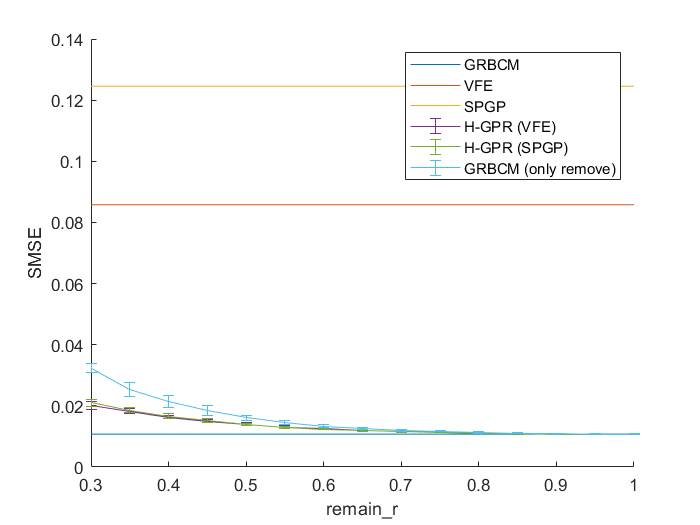

aamse = grbcm2_gr_smse(1:kti,:);
aamsll = grbcm2_gr_msll(1:kti,:);
mmse = mean(aamse);
mstd = std(aamse);
mmse_ro = mean(grbcm_gr_smse(1:kti,:));
mstd_ro = std(grbcm_gr_smse(1:kti,:));
mmse_sp = mean(grbcm2_spgp_gr_smse(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_smse(1:kti,:));

figure; hold on;
plot([min(grls), max(grls)], [grbcm0_smse,grbcm0_smse]);
plot([min(grls), max(grls)], [vfeSMSE_bl,vfeSMSE_bl]);
plot([min(grls), max(grls)], [spgpSMSE_bl,spgpSMSE_bl]);
errorbar(grls, mmse, mstd);
errorbar(grls, mmse_sp, mstd_sp);
errorbar(grls, mmse_ro, mstd_ro);
legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('remain\_r'); ylabel('SMSE');

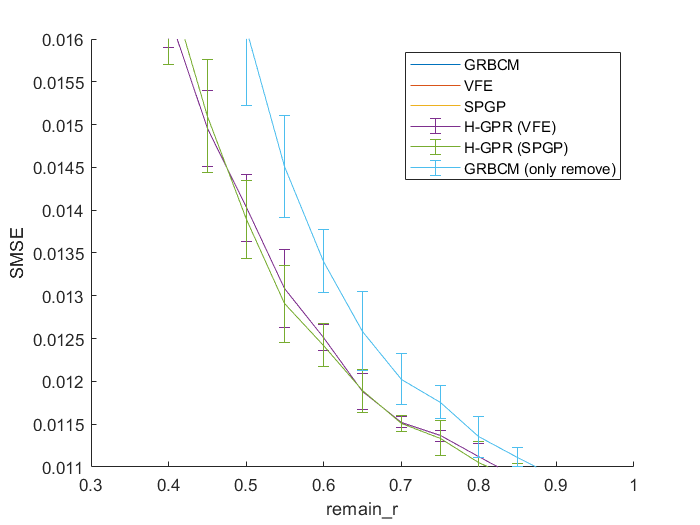

aamse = grbcm2_gr_smse(1:kti,:);
aamsll = grbcm2_gr_msll(1:kti,:);
mmse = mean(aamse);
mstd = std(aamse);
mmse_ro = mean(grbcm_gr_smse(1:kti,:));
mstd_ro = std(grbcm_gr_smse(1:kti,:));
mmse_sp = mean(grbcm2_spgp_gr_smse(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_smse(1:kti,:));

figure; hold on;
plot([min(grls), max(grls)], [grbcm0_smse,grbcm0_smse]);
plot([min(grls), max(grls)], [vfeSMSE_bl,vfeSMSE_bl]);
plot([min(grls), max(grls)], [spgpSMSE_bl,spgpSMSE_bl]);
errorbar(grls, mmse, mstd);
errorbar(grls, mmse_sp, mstd_sp);
errorbar(grls, mmse_ro, mstd_ro);
legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('remain\_r'); ylabel('SMSE');
ylim([0.011, 0.016]);

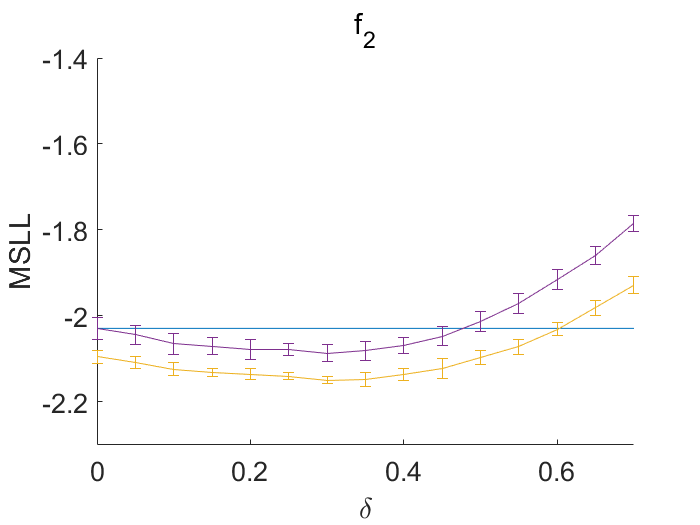

mmsll = mean(aamsll);
mstd = std(aamsll);
mmsll_ro = mean(grbcm_gr_msll(1:kti,:));
mstd_ro = std(grbcm_gr_msll(1:kti,:));
mmsll_sp = mean(grbcm2_spgp_gr_msll(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_msll(1:kti,:));
figure; hold on;
plot([0, 0.7], [grbcm0_msll,grbcm0_msll]);
plot([0, 0.7], [vfeMSLL_bl,vfeMSLL_bl]);
%plot([min(grls), max(grls)], [spgpMSLL_bl,spgpMSLL_bl]);
errorbar(0:0.05:0.7, flip(mmsll), flip(mstd));
%errorbar(grls, mmsll_sp, mstd_sp);
errorbar(0:0.05:0.7, flip(mmsll_ro), flip(mstd_ro));
%legend('GRBCM', 'VFE', 'H-GPR (VFE)', 'GRBCM (only remove)');
%legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('\delta'); ylabel('MSLL');
ylim([-2.3, -1.4]);
xlim([0, 0.7]);
title('f_2')
set(gca,'fontsize', 16);

fprintf('Best SMSE (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmse));

Best SMSE (GRBCM+VFE, dcs 150, ecs 150): 0.01055557


fprintf('Best MSLL (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmsll));

Best MSLL (GRBCM+VFE, dcs 150, ecs 150): -2.14919562



fprintf('Best SMSE (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmse_sp));

Best SMSE (GRBCM+SPGP, dcs 150, ecs 150): 0.01051441


fprintf('Best MSLL (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmsll_sp));

Best MSLL (GRBCM+SPGP, dcs 150, ecs 150): -2.13733784
